# Adding more complex constraints on a model 

## Authors: Thomas Pfau,Life Sciences Reasearch Unit, University of Luxembourg, Luxembourg.

## Reviewers: 

## INTRODUCTION

The COBRA Toolbox offers the possibility to add additional constraints to a model, that are not direct flux constraints. One example is already indicated in the constraining Models tutorial (constraining a sum of fluxes above a certain bound), but there are plenty of other possibilities, that can be achieved using constraints.

The tools introduced in this tutorial are mainly aimed at developers who want to implement complex algorithms or formalisms within the COBRA Toolbox environment, but the basics are also useful to integrate specific properties of a model or specific literature data. The section "The COBRA Model structure" is aimed at developers and can be skipped by users who don't to go into the details.

## The COBRA Model structure

In general, the COBRA toolbox represents a model in a struct, using multiple fields to represent the different properties of the model. Of particular interest for analysis are the stoichiometric Matrix S (which represents the metabolic stoichiometries of the reactions in the model). nder normal circumstances, this matrix can directly be translated into the linear problem matrix A of a Problem struct as used by the Toolbox. However, since there are several algorithms which aim at manipulating reactions or metabolites, it is important to draw a distinction between the stoichiometric matrix S and any other constraints or variables which can be added to the model.

Therefore 3 additional matricies exist, where such information can be stored:

E - The matrix indicating the influence of additional variables on metabolite levels.

C - The matrix of additional constraints on the reactions, which are not derived from the steady state condition and

D - The matrix of interactions between additional Constraints and additional variables.

Overall A COBRA model will be translated into a Linear problem by combining these matrices in the following way:


$$LPproblem\ldotp A=\text{ }\left\lbrack \begin{array}{c}
model\ldotp S & model\ldotp E\\
model\ldotp C & model\ldotp D
\end{array}\right\rbrack$$
 

The Cobra toolbox allows one sided inequality constraints and equality constraints on a model. i.e. there is currently no mechanism to add a constraint like:


$$c_{low} \le v_{R1} \le c_{high}$$


directly. Instead it would be necessary to add the two constraints:


$$c_{low} \le v_{R1}$$


and


$$ v_{R1} \le c_{high}$$


which is commonly what solvers will translate these constraints into anyways. 

It is best practice to not manually alter the sizes of these matrices, but to use the functions appropriate model manipulation functions (addReaction/addMultipleReactions, addMetabolite/addMultipleMetabolites, addCOBRAVariables, addCOBRAConstraints). These functions will ensure, that the model structure stays in sync, and all necessary fields are updated appropriately. There is a convenience function to create the corresponding LPproblem struct to the given model: buildLPproblemFromModel(). This function will create and initialize all necessary fields and builds the corresponding LP problem. Any additional modifications of the LP problem imposed by an algorithm should be done on this LP and not on the original model structure.

## PROCEDURE

Initially you will load a model for which we want to add a few additional constraints. The model used will be the simple ecoli core model:

initCobraToolbox
model = getDistributedModel('ecoli_core_model.mat');
%Create a copy for comparisons
model_orig = model;

We will add a restriction on the activity of the two aconitase proteins present in ecoli (aconA and aconB), which catalyse two steps in the Citric acid cycle (see below)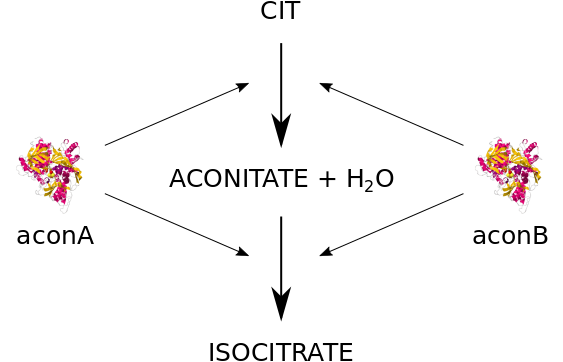

 From UNIPROT[1], the Km value of aconitase acting on citrate is 6.13 and 23.8 umol/min/mg for aconA and aconB respectively. For cis-aconitate the values are 14.5 and 39.1 umol/min/mg, respectively.

aconACit = 6.13;
aconAAcon = 14.5;
aconBCit = 23.8;
aconBAcon = 39.1;

Now, there are two genes which code for aconitase in the ecoli core model: b0118 (aconB) and b1276 (aconA). Both the Citrate hydratase and the aconitatde dehydratase have the same GPR rule: (b0118 or b1276), so they can both use this enzyme. 

aconAgene = 'b1276';
aconBgene = 'b0118';

We would like to add a constraint, that not only restricts the activity of these two reactions but also ensures, that the turnover rates are considered. Lets assume, that we are looking at 1 minute time steps in our simulation. that means, that one mg of aconA can suppoert a flux of 6.13 umol/min through the reaction ACONTa:

printRxnFormula(model,'rxnAbbrList',{'ACONTa'},'gprFlag', true);

OR a flux of 14.5 umol/min through ACONTb.

printRxnFormula(model,'rxnAbbrList',{'ACONTb'},'gprFlag', true);

However, it will not be able to do both at the same time. Therefore, we can assume, that in addition to its normal metabolites, the reaction also consumes some of the enzyme (for this time step). However, both reactions can also be catalysed by aconB, so they might actually not consume any of aconA. Therefore, we need additional Constraints, that represents the activity through these two reactions. And we need additional variables that represent the efficiency of one mg of protein to catalyse the reactions.

Essentially, we have to encode:

A: The availability of the given proteins 

B: The efficiency of a protein to catalyse a specific reaction

C: The usage of that protein by the respective reaction.

And we will do so in this tutorial

## Adding availability Variables.

The rxns field is intended to only represent reactions from the model, so if an additional variable is required for a specific task, this variable should not be generated in the rxns field, but in a distinct field for this kind of variables. So we will add availability variables, which can be thought of exchange reaction for the enzymes. Lets assume, that we have a total of 0.02 mg of aconA and a total of 0.01 mg of aconB (these numbers are completely arbitrary).

aconAAmount = 0.02;
aconBAmount = 0.01;
aconVars = {'aconA','aconB'};
model = addCOBRAVariables(model,aconVars,'lb',[0;0],'ub',[aconAAmount;aconBAmount]);

## Adding usage Efficiencies

We further need a conversion between the used amount of aconA and the potential flux through ACONTa. We also need this for ACONTb and the same for aconB.

linkedReactions = {'ACONTa','ACONTb'};
for enzyme = 1:numel(aconVars)
    for linkedReaction = 1:numel(linkedReactions)
        model = addCOBRAVariables(model,{strcat(aconVars{enzyme},'to',linkedReactions{linkedReaction})},'lb',0);
    end
end


Now, we can add the respective constraints.

The first constraint is for the amount of aconA, which should be steady (i.e. not more than made available by the aconA variable). More precisely, The amount enzyme made available for ACONTa and ACONTb, should be balanced with the amount of enzyme made available by the aconA variable.

model = addCOBRAConstraints(model,{'aconAtoACONTa','aconAtoACONTb','aconA'},0, 'c',[-1,-1,1],...
    'dsense','E', 'ConstraintID', 'aconAAmount');

The same constraint is introduced for aconB

model = addCOBRAConstraints(model,{'aconBtoACONTa','aconBtoACONTb','aconB'},0, 'c',[-1,-1,1],...
    'dsense','E', 'ConstraintID', 'aconBAmount');

Now, we also add the efficiencies:

model = addCOBRAConstraints(model,{'aconAtoACONTa','aconBtoACONTa','ACONTa'},0, 'c',[aconACit,aconBCit,-1],...
    'dsense','E', 'ConstraintID', 'ACONTaFlux');
model = addCOBRAConstraints(model,{'aconAtoACONTb','aconBtoACONTb','ACONTb'},0, 'c',[aconAAcon,aconBAcon,-1],...
    'dsense','E', 'ConstraintID', 'ACONTbFlux');

Now, we have a a system, in which the two aconitase reactions are competing for the available enzymes. 

## Analysing the effects of the constraints

If we compare the results of a simple FBA optimization of the original model, and the constrained model:

orig_sol = optimizeCbModel(model_orig)
restricted_sol = optimizeCbModel(model)

We can easily see, that the obtained objective of the modified model is lower than that of the original model.

## Modifiying Variables and Constraints

Variables and constraints can be altered by the functions changeCOBRAVariable and changeCOBRAConstraint respectively. Modifications on a variable include the adjustment of upper and lower bounds (by the parameters lb/ub) as well as the objective value (c) and the descriptive name (parameter 'Name').

Modifying constraints allows the adjustment of the coefficients (parameter 'c') of the constraint as well as the directionality (parameter 'dsense') and right hand side ( parameter 'd') of the constraint as well as the name (same as for variables). There are several ways to update the coefficients: Either a full row (including both values for the C and the E matrix (if any)) needs to be provided, or the IDs along with the coefficients (similar to the situation when generating the constraints) need to be provided. It is important to note, that ALL coefficients will be reset, if a constraint is modified using the changeCOBRAConstraint function.

An example of these functions is provided below:

If we increase the abundance of aconA (by increasing its upper bound)

model = changeCOBRAVariable(model,'aconA','ub',0.06);
less_restricted_sol = optimizeCbModel(model)

We can see, that the objective increases as more flux through the TCA is possible.

Similarily, if we reduce the efficiency of aconA on Citrate by 50%:

model = changeCOBRAConstraints(model,'ACONTaFlux','idList',{'aconAtoACONTa','aconBtoACONTa','ACONTa'},...
    'c',[aconACit*0.5,aconBCit,-1]);
less_efficient_aconA = optimizeCbModel(model)

We can again see the objective drop.

While we only used a very simple example for this tutorial, this interplay can improve predictive qualities substantially (for more have a look at e.g. [2])

## References

[1] The UniProt Consortium, UniProt: the universal protein knowledgebase, Nucleic Acids Res. 45: D158-D169 (2017)

[2] Sánchez et al, Improving the phenotype predictions of a yeast genome-scale metabolic model by incorporating enzymatic constraints, Mol Sys Biol, 13:935 (2017)